%Project: 1.0
% MATLAB Code for Minimizing Energy Consumption in Computer Networks
%Author: Mohammad Raihan Uddin
%Course: CPE-648
%Faculty: Dr. Dinh C. Nguyen

% Clear previous variables and console
yalmip('clear')
clc;
clear all;
close all;

% Parameters
U = 1; % Number of user devices

% System Parameters
BW = 20e6; % Total available bandwidth [Hz]

% Initial guesses and bounds for variables
f_u_min = 1.2e9;       % Minimum CPU frequency [Hz]
f_u_i = 4e9;           % Initial CPU frequency [Hz]
p_u_min = 0.002;       % Minimum transmit power [Watts]
p_u_i = 2.0;           % Initial transmit power [Watts]
x_u_i = 5;             % Initial slack variable [seconds]

L_max = 50;            % Maximum allowed latency [seconds]
C_u = 1000;            % Number of CPU cycles per data unit [cycles/bit]
D_u = 500e3;           % Data volume to process [bits]
N_u = 5;               % Number of users (for bandwidth division in FDMA)
b_u = BW / N_u;        % Bandwidth allocated to each user [Hz]
g_u_dB = -64;          % Channel gain in dB
g_u = 10^(g_u_dB / 10);% Channel gain (linear)
n0_dBmHz = -174;       % Noise power spectral density [dBm/Hz]
n0 = 10^((n0_dBmHz - 30) / 10); % Noise power spectral density [W/Hz]
F_u = 4e9;             % Maximum CPU frequency [Hz]
P_u_dBm = 33;          % Maximum transmit power [dBm]
P_u = 10^((P_u_dBm - 30) / 10); % Maximum transmit power [Watts]
E_u_max = 20;          % Maximum energy consumption [Joules]
zeta_u = 1e-28;        % Energy efficiency coefficient [Joule/(cycle^2)]
s = 4e8;               % Size of data to be offloaded [bits]
tol = 1e-4;            % Convergence tolerance

max_iter = 10;         % Number of SCA iterations

% Initialize optimization variables
f_u = sdpvar(1,1);     % CPU frequency [Hz]
p_u = sdpvar(1,1);     % Transmit power [Watts]
x_u = sdpvar(1,1);     % Slack variable [seconds]

% Assign initial values to variables
assign(f_u, f_u_i);
assign(p_u, p_u_i);
assign(x_u, x_u_i);

% Arrays to store results
energy_values = zeros(max_iter, 1);
f_u_values = zeros(max_iter, 1);
p_u_values = zeros(max_iter, 1);
x_u_values = zeros(max_iter, 1);
latency_values = zeros(max_iter, 1);
variable_changes = zeros(max_iter, 1);

% Remove convergence check to run for exactly max_iter iterations
for iter = 1:max_iter
    Constraints = [];

    % Variable bounds
    Constraints = [Constraints, f_u_min <= f_u <= F_u];
    Constraints = [Constraints, p_u_min <= p_u <= P_u];

    % Latency constraint
    latency_expr = (C_u * D_u) / f_u + x_u <= L_max;
    Constraints = [Constraints, latency_expr];

    % Energy consumption during execution
    E_exec = zeta_u * C_u * D_u * f_u^2;

    % Linearize the offloading energy term
    E_offload = (1/2) * (p_u_i / x_u_i) * x_u^2 + (1/2) * (x_u_i / p_u_i) * p_u^2;

    % Total energy consumption
    E_total = E_exec + E_offload;

    % Energy constraint (optional)
    Constraints = [Constraints, E_total <= E_u_max];

    % Offloading rate constraint (linearized)
    denom1 = (p_u * g_u) + (b_u * n0) + eps;
    denom2 = (p_u_i * g_u) + (b_u * n0) + eps;
    denom3 = p_u * g_u + eps;

    ex1 = (s * log(2)) / b_u;

    % Compute current values
    r_u_i = (p_u_i * g_u) / (b_u * n0);
    log_term_i = log(1 + r_u_i);

    % Gradients for linearization
    grad_pu = (x_u_i * g_u) / (b_u * n0 * (1 + r_u_i));
    grad_xu = log(1 + r_u_i);

    % Linearized left-hand side
    lhs = x_u_i * log_term_i + grad_xu * (x_u - x_u_i) + grad_pu * (p_u - p_u_i);

    % Offloading rate constraint
    Constraints = [Constraints, lhs >= ex1];

    % Objective function: minimize total energy
    Objective = E_total;

    % Solver options
    options = sdpsettings('verbose', 1, 'solver', 'fmincon', 'usex0', 1, 'debug', 1, 'showprogress', 1, 'fmincon.Algorithm', 'interior-point', 'fmincon.Display', 'iter-detailed');

    % Solve the optimization problem
    diagnostics = optimize(Constraints, Objective, options);

    % Check if the problem was solved successfully
    if diagnostics.problem == 0
        % Retrieve optimized values
        f_u_val = value(f_u);
        p_u_val = value(p_u);
        x_u_val = value(x_u);
        E_total_val = value(E_total);

        % Store results
        energy_values(iter) = E_total_val;
        f_u_values(iter) = f_u_val;
        p_u_values(iter) = p_u_val;
        x_u_values(iter) = x_u_val;
        latency_values(iter) = (C_u * D_u) / f_u_val + x_u_val;

        % Calculate the change in variables (for convergence analysis)
        if iter > 1
            variable_change = norm([f_u_values(iter) - f_u_values(iter - 1); p_u_values(iter) - p_u_values(iter - 1); x_u_values(iter) - x_u_values(iter - 1)]);
            variable_changes(iter) = variable_change;
        end

        % Display iteration results
        fprintf('Iteration %d:\n', iter);
        fprintf('  f_u = %.2e Hz\n', f_u_val);
        fprintf('  p_u = %.6f W\n', p_u_val);
        fprintf('  x_u = %.6f s\n', x_u_val);
        fprintf('  Latency = %.6f s\n', latency_values(iter));
        fprintf('  Energy = %.6f J\n', E_total_val);
        if iter > 1
            fprintf('  Variable Change Norm: %.6e\n\n', variable_change);
        else
            fprintf('\n');
        end

        % Update variables for next iteration
        f_u_i = f_u_val;
        p_u_i = p_u_val;
        x_u_i = x_u_val;

        % Assign updated values
        assign(f_u, f_u_i);
        assign(p_u, p_u_i);
        assign(x_u, x_u_i);
    else
        % If optimization failed
        disp('Optimization failed or did not converge.');
        disp(diagnostics.info);
        break; % Exit the loop if the optimization fails
    end
end

+ Solver chosen : fmincon-geometric
+ Processing objective function
+ Processing constraints
+ Solver chosen : fmincon-standard
+ Processing objective function
+ Processing constraints
+ Calling FMINCON
Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    7.307813e+00    0.000e+00    1.911e+00
    1       2    4.990355e+00    0.000e+00    8.160e-01    1.172e+00
    2       3    4.415059e+00    0.000e+00    1.764e-01    3.610e-01
    3       4    4.450469e+00    0.000e+00    1.751e-01    2.242e-01
    4       5    4.434421e+00    0.000e+00    1.072e-01    7.226e-02
    5       6    4.420640e+00    0.000e+00    9.675e-02    2.402e-01
    6       7    4.331999e+00    0.000e+00    3.285e-02    3.141e-01
    7       8    4.304491e+00    0.000e+00    7.346e-03    3.091e-01
    8       9    

Iteration 1:


  f_u = 1.20e+09 Hz


  p_u = 0.094290 W


  x_u = 4.178754 s


  Latency = 4.595419 s


  Energy = 3.575510 J


+ Solver chosen : fmincon-geometric
+ Processing objective function
+ Processing constraints
+ Solver chosen : fmincon-standard
+ Processing objective function
+ Processing constraints
+ Calling FMINCON
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.660168e-01    8.000e+00    9.229e-02
    1       2    4.603772e-01    0.000e+00    8.451e-01    6.772e-01
    2       3    3.940654e-01    0.000e+00    1.177e+00    2.267e-01
    3       4    4.673263e-01    0.000e+00    5.143e-02    3.918e-01
    4       5    4.904011e-01    0.000e+00    5.146e-02    1.676e-01
    5       6    3.922737e-01    0.000e+00    2.569e-01    4.839e-01
    6       7    3.815712e-01    0.000e+00    2.140e-02    5.491e-02
    7       8    3.561379e-01    0.000e+00    5.370e-03    1.336e-01
    8       9    3.541803e-01    0.000e+00    3.090e-03    1.140e-02
    9      10    3.539696e-01    0.000e+00    3.957

Iteration 2:


  f_u = 1.20e+09 Hz


  p_u = 0.007668 W


  x_u = 4.985594 s


  Latency = 5.402259 s


  Energy = 0.353734 J


  Variable Change Norm: 8.114766e-01



+ Solver chosen : fmincon-geometric
+ Processing objective function
+ Processing constraints
+ Solver chosen : fmincon-standard
+ Processing objective function
+ Processing constraints
+ Calling FMINCON
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    1.102323e-01    8.671e+00    7.196e-03
    1       2    2.375106e-01    0.000e+00    5.597e+00    1.447e-02
    2       3    5.127176e-01    0.000e+00    3.881e-01    4.507e-01
    3       4    3.383844e-01    0.000e+00    5.012e+00    1.586e-01
    4       5    1.678612e-01    0.000e+00    1.527e+00    7.631e-01
    5       6    1.680488e-01    0.000e+00    1.837e+00    4.412e-01
    6       7    1.796428e-01    0.000e+00    1.099e+00    8.763e-01
    7       8    2.011710e-01    0.000e+00    2.656e-01    1.543e+00
    8       9    1.490428e-01    0.000e+00    1.329e-01    1.135e+00
    9      10    1.319499e-01    0.000e+00    1.006

Iteration 3:


  f_u = 1.20e+09 Hz


  p_u = 0.002001 W


  x_u = 6.001455 s


  Latency = 6.418120 s


  Energy = 0.101001 J


  Variable Change Norm: 1.015877e+00



+ Solver chosen : fmincon-geometric
+ Processing objective function
+ Processing constraints
+ Solver chosen : fmincon-standard
+ Processing objective function
+ Processing constraints
+ Calling FMINCON
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    8.400635e-02    4.379e+00    1.849e-04
    1       2    8.940109e-01    0.000e+00    6.422e+01    5.383e+00
    2       3    1.510840e+00    0.000e+00    8.111e-01    4.118e+00
    3       5    4.954086e-01    0.000e+00    2.111e+01    4.148e+00
    4       6    1.289344e-01    0.000e+00    5.791e-02    3.469e+00
    5       7    2.153365e-01    0.000e+00    5.285e-02    2.890e+00
    6       8    1.970441e-01    0.000e+00    1.044e-01    1.206e+00
    7       9    1.952549e-01    0.000e+00    5.030e-02    1.538e-01
    8      10    1.252373e-01    0.000e+00    5.633e-01    3.927e+00
    9      11    9.570344e-02    0.000e+00    6.105

Iteration 4:


  f_u = 1.20e+09 Hz


  p_u = 0.002000 W


  x_u = 6.406443 s


  Latency = 6.823108 s


  Energy = 0.084841 J


  Variable Change Norm: 4.049896e-01



+ Solver chosen : fmincon-geometric
+ Processing objective function
+ Processing constraints
+ Solver chosen : fmincon-standard
+ Processing objective function
+ Processing constraints
+ Calling FMINCON
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    8.481378e-02    0.000e+00    3.585e-07

Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the 

Iteration 5:


  f_u = 1.20e+09 Hz


  p_u = 0.002000 W


  x_u = 6.406443 s


  Latency = 6.823108 s


  Energy = 0.084814 J


  Variable Change Norm: 0.000000e+00



+ Solver chosen : fmincon-geometric
+ Processing objective function
+ Processing constraints
+ Solver chosen : fmincon-standard
+ Processing objective function
+ Processing constraints
+ Calling FMINCON
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    8.481378e-02    0.000e+00    3.585e-07

Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the 

Iteration 6:


  f_u = 1.20e+09 Hz


  p_u = 0.002000 W


  x_u = 6.406443 s


  Latency = 6.823108 s


  Energy = 0.084814 J


  Variable Change Norm: 0.000000e+00



+ Solver chosen : fmincon-geometric
+ Processing objective function
+ Processing constraints
+ Solver chosen : fmincon-standard
+ Processing objective function
+ Processing constraints
+ Calling FMINCON
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    8.481378e-02    0.000e+00    3.585e-07

Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the 

Iteration 7:


  f_u = 1.20e+09 Hz


  p_u = 0.002000 W


  x_u = 6.406443 s


  Latency = 6.823108 s


  Energy = 0.084814 J


  Variable Change Norm: 0.000000e+00



+ Solver chosen : fmincon-geometric
+ Processing objective function
+ Processing constraints
+ Solver chosen : fmincon-standard
+ Processing objective function
+ Processing constraints
+ Calling FMINCON
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    8.481378e-02    0.000e+00    3.585e-07

Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the 

Iteration 8:


  f_u = 1.20e+09 Hz


  p_u = 0.002000 W


  x_u = 6.406443 s


  Latency = 6.823108 s


  Energy = 0.084814 J


  Variable Change Norm: 0.000000e+00



+ Solver chosen : fmincon-geometric
+ Processing objective function
+ Processing constraints
+ Solver chosen : fmincon-standard
+ Processing objective function
+ Processing constraints
+ Calling FMINCON
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    8.481378e-02    0.000e+00    3.585e-07

Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the 

Iteration 9:


  f_u = 1.20e+09 Hz


  p_u = 0.002000 W


  x_u = 6.406443 s


  Latency = 6.823108 s


  Energy = 0.084814 J


  Variable Change Norm: 0.000000e+00



+ Solver chosen : fmincon-geometric
+ Processing objective function
+ Processing constraints
+ Solver chosen : fmincon-standard
+ Processing objective function
+ Processing constraints
+ Calling FMINCON
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    8.481378e-02    0.000e+00    3.585e-07

Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the 

Iteration 10:


  f_u = 1.20e+09 Hz


  p_u = 0.002000 W


  x_u = 6.406443 s


  Latency = 6.823108 s


  Energy = 0.084814 J


  Variable Change Norm: 0.000000e+00



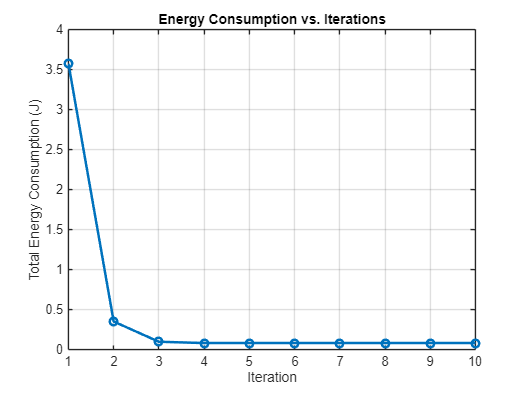


% Trim arrays if the loop exited early
iterations = 1:iter;
energy_values = energy_values(1:iter);
f_u_values = f_u_values(1:iter);
p_u_values = p_u_values(1:iter);
x_u_values = x_u_values(1:iter);
latency_values = latency_values(1:iter);
variable_changes = variable_changes(1:iter);

% Plot Energy vs Iterations
figure;
plot(iterations, energy_values, '-o', 'LineWidth', 2);
xlabel('Iteration');
ylabel('Total Energy Consumption (J)');
title('Energy Consumption vs. Iterations');
grid on;

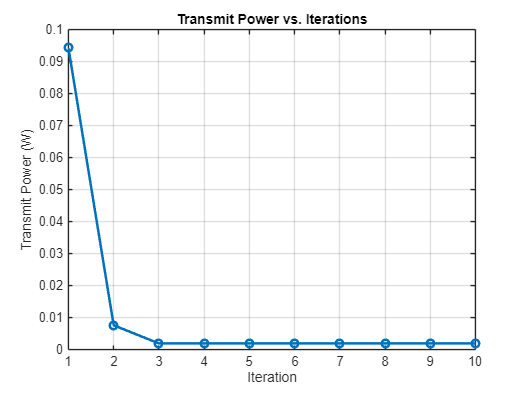


% Plot Transmit Power over Iterations
figure;
plot(iterations, p_u_values, '-o', 'LineWidth', 2);
xlabel('Iteration');
ylabel('Transmit Power (W)');
title('Transmit Power vs. Iterations');
grid on;

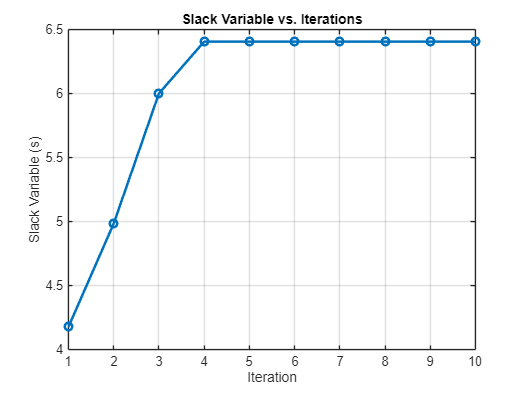


% Plot Slack Variable over Iterations
figure;
plot(iterations, x_u_values, '-o', 'LineWidth', 2);
xlabel('Iteration');
ylabel('Slack Variable (s)');
title('Slack Variable vs. Iterations');
grid on;

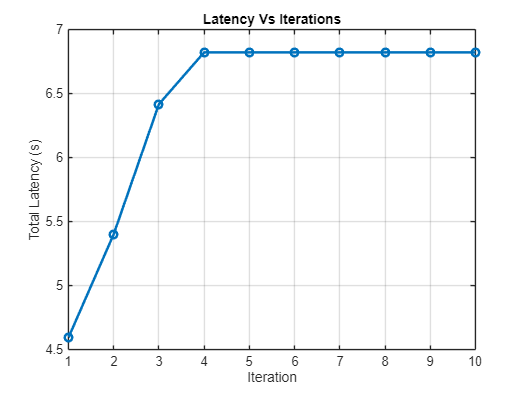


% Plot Latency over Iterations
figure;
plot(iterations, latency_values, '-o', 'LineWidth', 2);
xlabel('Iteration');
ylabel('Total Latency (s)');
title('Latency Vs Iterations');
grid on;

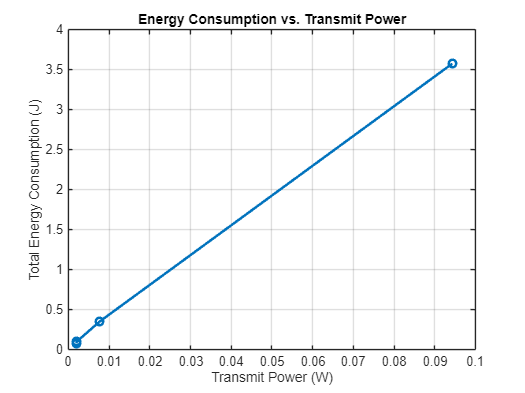


% Plot Energy Consumption vs. Transmit Power
figure;
plot(p_u_values, energy_values, '-o', 'LineWidth', 2);
xlabel('Transmit Power (W)');
ylabel('Total Energy Consumption (J)');
title('Energy Consumption vs. Transmit Power');
grid on;

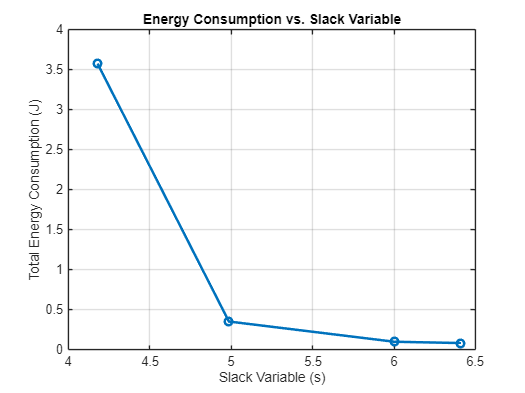


% Plot Energy Consumption vs. Slack Variable
figure;
plot(x_u_values, energy_values, '-o', 'LineWidth', 2);
xlabel('Slack Variable (s)');
ylabel('Total Energy Consumption (J)');
title('Energy Consumption vs. Slack Variable');
grid on;


% Display final results
if diagnostics.problem == 0
    fprintf('Final Results after %d iterations:\n', iter);
    fprintf('  Optimal CPU Frequency (f_u): %.2e Hz\n', f_u_val);
    fprintf('  Optimal Transmit Power (p_u): %.6f W\n', p_u_val);
    fprintf('  Optimal Slack Variable (x_u): %.6f s\n', x_u_val);
    fprintf('  Total Latency: %.6f s\n', latency_values(end));
    fprintf('  Total Energy Consumption: %.6f J\n', E_total_val);
else
    disp('Could not display final results because optimization did not succeed.');
end

Final Results after 10 iterations:


  Optimal CPU Frequency (f_u): 1.20e+09 Hz


  Optimal Transmit Power (p_u): 0.002000 W


  Optimal Slack Variable (x_u): 6.406443 s


  Total Latency: 6.823108 s


  Total Energy Consumption: 0.084814 J
